clear z_ub z_lb y_ub y_lb x_ub x_lb x0z x0y x0x 
data = datat;
x0z = 0;
x0y = 0;
x0x = 0;
z_lb = -40;
z_ub = 40;
y_lb = -40;
y_ub = 40;
x_lb = -40;
x_ub = 40;

% Create optimization variables
Z_angle = optimvar("Z_angle","LowerBound",z_lb,"UpperBound",z_ub);
Y_angle = optimvar("Y_angle","LowerBound",y_lb,"UpperBound",y_ub);
X_angle = optimvar("X_angle","LowerBound",x_lb,"UpperBound",x_ub);

% Set initial starting point for the solver
initialPoint.Z_angle = x0z;
initialPoint.Y_angle = x0y;
initialPoint.X_angle = x0x;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@findAngleObjectiveFcn,Z_angle,Y_angle,...
    X_angle,data);

% 设置非默认求解器选项
options = optimoptions("fmincon","Display","iter","PlotFcn",["optimplotx",...
    "optimplotfvalconstr","optimplotfval","optimplotstepsize"]);

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       X_angle, Y_angle, Z_angle

	minimize :
       findAngleObjectiveFcn(Z_angle, Y_angle, X_angle, extraParams{1})

       extraParams


	variable bounds:
       -40 <= X_angle <= 40

       -40 <= Y_angle <= 40

       -40 <= Z_angle <= 40



Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    2.204836e-02    0.000e+00    1.851e-03
    1       8    2.204469e-02    0.000e+00    1.842e-03    1.910e-03
    2      12    2.202629e-02    0.000e+00    1.841e-03    9.594e-03
    3      16    2.193447e-02    0.000e+00    1.836e-03    4.794e-02
    4      20    2.148028e-02    0.000e+00    1.811e-03    2.391e-01
    5      24    1.932828e-02    0.000e+00    1.695e-03    1.178e+00
    6      28    1.099243e-02    0.000e+00    1.222e-03    5.495e+00
    7      32    8.061735e-04    0.000e+00    1.978e-04    1.415e+01
    8      36    4.885443e-04    0.000e+00    1.501e-04    2.437e+00
    9      40    4.379333e-04    0.000e+00    1.854e-04    1.234e+00
   10      44    4.343378e-04    0.000e+00    1.964e-04    3.852e-01
   11      48    4.341987e-04    0.000e+00    1.983e-04    6.909e-02
   12      52   

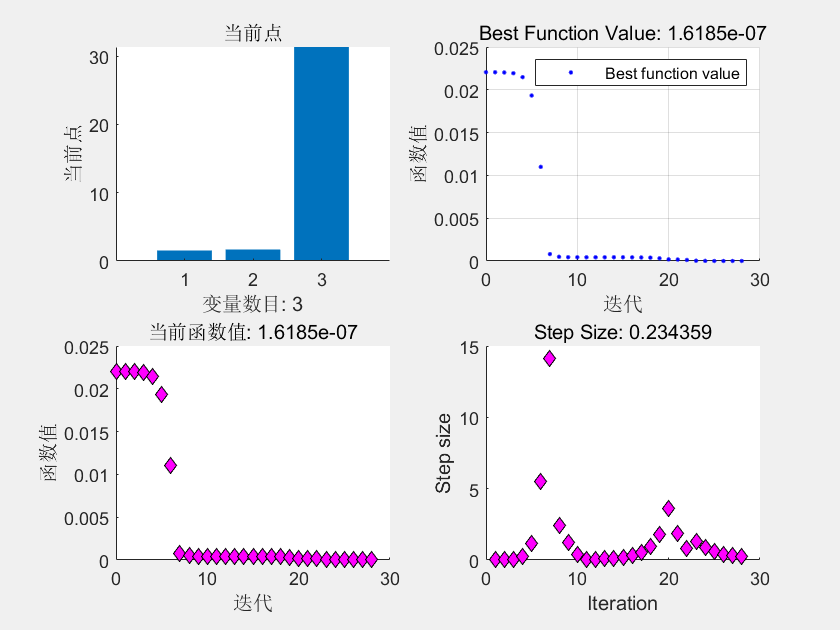


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","fmincon","Options",options);


% Display results
solution

solution = 包含以下字段的 struct :
    X_angle: 1.5453
    Y_angle: 1.6869
    Z_angle: 31.3521


reasonSolverStopped

reasonSolverStopped =     OptimalSolution


objectiveValue

objectiveValue = 1.6185e-07


% 清除变量
clearvars Z_angle Y_angle X_angle initialPoint options reasonSolverStopped...
    objectiveValue